Image = imread('HotCrossBuns.jpg');
[x, y] = createMask2(Image);
W = x((160:230), (162:200));
Map = zeros(71,500);
Map(1:71, 1:39) = W;
Map(20:21, :) = 1;
Map(28:29, :) = 1;
Map(36:37, :) = 1;
Map(44:45, :) = 1;
Map(52:53, :) = 1;
BackGroundNote = Map(:, 40:51);

Ball = readmatrix('ball.csv');
Ball = logical(Ball(1:8,1:12));


imshow(BackGroundNote)

E1_4  = LineNoteMap(21, BackGroundNote);
C1_4  = LineNoteMap(29, BackGroundNote);
A1_4  = LineNoteMap(37, BackGroundNote);
F1_4  = LineNoteMap(45, BackGroundNote);
FL1_4 = LineNoteMap(17, BackGroundNote);
DL1_4 = LineNoteMap(25, BackGroundNote);
BL1_4 = LineNoteMap(33, BackGroundNote);
GL1_4 = LineNoteMap(41, BackGroundNote);
EL1_4 = LineNoteMap(49, BackGroundNote);

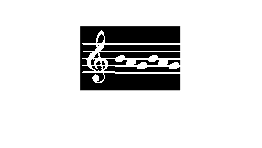


Line = [W BL1_4 A1_4 GL1_4 BL1_4 A1_4 GL1_4];
imshow(Line)

Notes = Getter(Line)

Sz =     71   111


Notes = ' BL1_4 A1_4 GL1_4 BL1_4 A1_4 GL1_4'

function [Caught] = Getter(im)
	E.value = NoteMap(21);
	E.name = 'E1_4';       
	C.value = NoteMap(29);
	C.name = 'C1_4';       
	A.value = NoteMap(37);
	A.name = 'A1_4';       
	F.value = NoteMap(45);
	F.name = 'F1_4';
	FL.value = NoteMap(17);
	FL.name = 'FL1_4';
	DL.value = NoteMap(25);
	DL.name = 'DL1_4';
	BL.value = NoteMap(33);
	BL.name = 'BL1_4';
	GL.value = NoteMap(41);
	GL.name = 'GL1_4';
	EL.value = NoteMap(49);
	EL.name = 'EL1_4';
	
	Masks = [E C A F FL DL BL GL EL];
	
	Caught = [];
	Sz = size(im)
	snd = Sz(2);
    for q = 1 : snd - 11
		for Test = Masks
			if (im(:, q:q + 11) & Test.value) == Test.value;
				Caught = [Caught ' ' Test.name];
			end
        end
	end
end


function [S] = LineNoteMap(NoteBase, BackGroundNote)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S = S | BackGroundNote;
S(z:x,:) = S(z:x,:) | Ball;
end

function [S] = NoteMap(NoteBase)
Ball = [   
   0   0   0   0   0   1   1   1   1   1   0   0;
   0   0   0   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   0   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   1   1   0;
   1   1   1   1   1   1   1   1   1   0   0   0;
   0   1   1   1   1   1   1   1   0   0   0   0;
];
S = zeros(71,12);
z = NoteBase;
x = NoteBase + 7;
S(z:x,:) = S(z:x,:) | Ball;
end

function [BW,maskedRGBImage] = createMask2(RGB)
% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.009;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 0.810;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
